Settings

Alles löschen

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

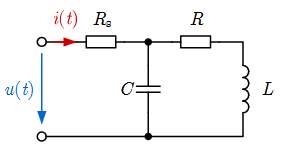

Erstellen symbolische Variablen

syms('R', 'positive')
syms('L', 'positive')
syms('C', 'positive')
syms('R_s', 'positive')
syms('t')
syms('s')

Numerische Werte

R_num = 8.2;
R_s_num = 108;
L_num = 660e-6;
C_num = 49e-9;
U_0 = 10

U_0 =     10.0000e+000

## Bestimmung von i(t) mithilfe der laplace Transformation

Berechnung der Impedanz

Z_ers = R_s + (1 /((s * C) + 1/(R + s * L)))

$$Z\_ers = R_{s}+\frac{1}{C\,s+\frac{1}{R+L\,s}}$$

U_e = U_0 *heaviside(t);
U_s = laplace(U_e);
I_s = U_s / Z_ers;

inverse Laplace-Transformation um i(t) zu erhalten 

i_t = ilaplace(I_s, s, t)

$$i\_t = \begin{array}{l} \frac{10}{R+R_{s}}+\frac{10\,R\,{\mathrm{e}}^{-\frac{t\,\left(L+C\,R\,R_{s}\right)}{2\,C\,L\,R_{s}}}\,\left(\cosh\left(\sigma_{1}\right)-\frac{C\,L\,R_{s}\,\sinh\left(\sigma_{1}\right)\,\left(\frac{L+C\,R\,R_{s}}{2\,C\,L\,R_{s}}+\frac{10\,L-10\,C\,R^{2}}{10\,C\,L\,R}\right)}{\sigma_{2}}\right)}{R_{s}\,\left(R+R_{s}\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\sigma_{2}}{C\,L\,R_{s}}\\ \sigma_{2}=\sqrt{\frac{C^{2}\,R^{2}\,{R_{s}}^{2}}{4}-\frac{C\,L\,R\,R_{s}}{2}-C\,L\,{R_{s}}^{2}+\frac{L^{2}}{4}} \end{array}$$

## Bestimmung Kenngrößen

Zeitkonstante tau 

Aus i_t kann die Zeitkonstante tau entnommen werden:

tau =1./( (L+C *R * R_s)/(2 * C* L *R_s))

$$tau = \frac{2\,C\,L\,R_{s}}{L+C\,R\,R_{s}}$$

tau_num = double(subs(tau, [R, L, C, R_s], [R_num, L_num, C_num, R_s_num]))

tau_num =      9.9310e-006

Frequenzen von Schwingungen

ch = children(children(i_t,2))

ch = 1×6 cell array
    {[R]}    {[1/R_s]}    {[exp(-(t*(L + C*R*R_s))/(2*C*L*R_s))]}    {[1/(R + R_s)]}    {[cosh((t*((C^2*R^2*R_s^2)/4 - (C*L*R*R_s)/2 - C*L*R_s^2 + L^2/4)^(1/2))/(C*L*R_s)) - (C*L*R_s*sinh((t*((C^2*R^2*R_s^2)/4 - (C*L*R*R_s)/2 - C*L*R_s^2 + L^2/4)^(1/2))/(C*L*R_s))*((L + C*R*R_s)/(2*C*L*R_s) + (- 10*C*R^2 + 10*L)/(10*C*L*R)))/((C^2*R^2*R_s^2)/4 - (C*L*R*R_s)/2 - C*L*R_s^2 + L^2/4)^(1/2)]}    {[10]}

terms = rewrite(simplify(ch{5}), 'cos')

$$terms = \begin{array}{l} \cos\left(\sigma_{1}\right)+\frac{\sin\left(\sigma_{1}\right)\,\left(-C\,R_{s}\,R^{2}+L\,R+2\,L\,R_{s}\right)\,\mathrm{i}}{R\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\sigma_{2}\,\mathrm{i}}{2\,C\,L\,R_{s}}\\ \sigma_{2}=\sqrt{C^{2}\,R^{2}\,{R_{s}}^{2}-2\,C\,L\,R\,R_{s}-4\,C\,L\,{R_{s}}^{2}+L^{2}} \end{array}$$

children(terms)

ans = 1×2 cell array
    {[cos((t*(C^2*R^2*R_s^2 - 2*C*L*R*R_s - 4*C*L*R_s^2 + L^2)^(1/2)*1i)/(2*C*L*R_s))]}    {[(sin((t*(C^2*R^2*R_s^2 - 2*C*L*R*R_s - 4*C*L*R_s^2 + L^2)^(1/2)*1i)/(2*C*L*R_s))*(- C*R_s*R^2 + L*R + 2*L*R_s)*1i)/(R*(C^2*R^2*R_s^2 - 2*C*L*R*R_s - 4*C*L*R_s^2 + L^2)^(1/2))]}

## Grafische Darstellung 

um i(t) darzustellen müssen symbolische Variablen durch numerische ersetzt werden, zudem werden die Wert für den Plot berechnet 

Um den i(t) korekt darzustellen muss die numerischen Lösung mit heaviside multipliziert werden und in eine matlabFunction umgewandelt werden

i_t_num = subs(i_t, [R, L, C, R_s], [R_num, L_num, C_num, R_s_num]) * heaviside(t);
t_plot = linspace(-1e-5, 1e-4, 1001);
i_t_num_plot = matlabFunction((i_t_num));
i_t_num_plot = i_t_num_plot(t_plot);

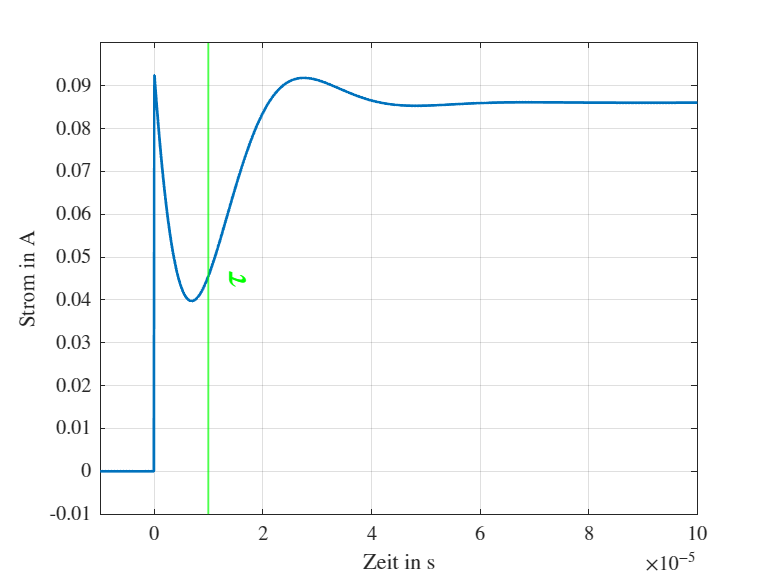

figure
plot(t_plot, i_t_num_plot, 'LineWidth', 1.5); % Corrected argument order
grid on;
xline(tau_num,'g', '$\tau$', 'LineWidth', 1, 'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle', 'LabelColor', 'g', 'Interpreter', 'latex', 'FontSize',20)
xlabel('Zeit in s');
ylabel('Strom in A');
xlim([-1e-5, 1e-4])
ylim([-1e-2, 1e-1])